Use ColoredNoise from MATLAB's DSP toolbox to generate three different kinds of noise:

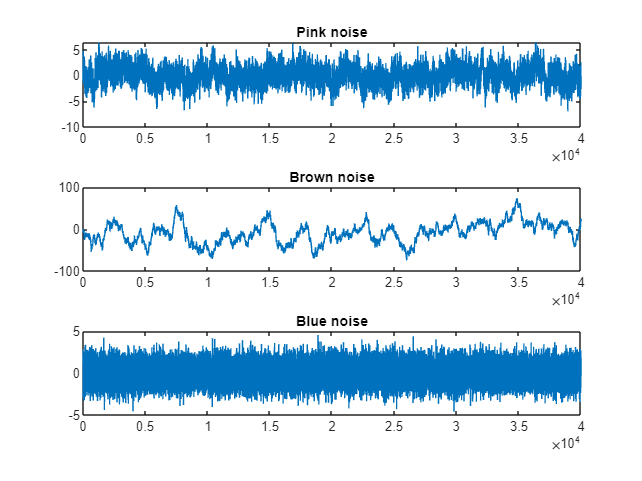

fsNoise = 8000;
channels = 1;

noisegenerator = dsp.ColoredNoise('pink', fsNoise*5, channels, OutputDataType='single');
pinkNoise = noisegenerator();

noisegenerator = dsp.ColoredNoise('brown', fsNoise*5, channels, OutputDataType='single');
brownNoise = noisegenerator();

noisegenerator = dsp.ColoredNoise('blue', fsNoise*5, channels, OutputDataType='single');
blueNoise = noisegenerator();

figure,
subplot(3,1,1), plot(pinkNoise), title("Pink noise");
subplot(3,1,2), plot(brownNoise), title("Brown noise");
subplot(3,1,3), plot(blueNoise), title("Blue noise");

Load a speech sample, downsample (for comparison with model outputs later...?), and create three noised signals:

%sound(pinkNoise,fsNoise)

[speechExample, fsSpeech] = audioread("sample2.wav");
speechDownsampled = mydownsample(speechExample, fsSpeech, fsNoise);

dur = length(speechDownsampled);

noisyAudioPink = add_noise(speechDownsampled, pinkNoise);
noisyAudioBrown = add_noise(speechDownsampled, brownNoise);
noisyAudioBlue = add_noise(speechDownsampled, blueNoise);

Plot the signals:

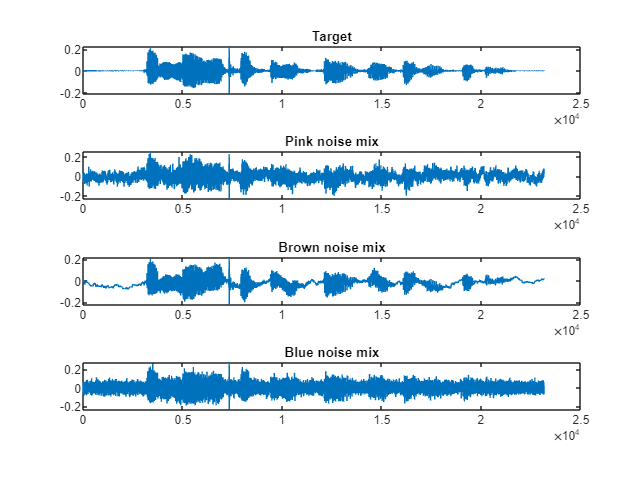

figure,
subplot(4,1,1), plot(speechDownsampled), title("Target");
subplot(4,1,2), plot(noisyAudioPink), title("Pink noise mix");
subplot(4,1,3), plot(noisyAudioBrown), title("Brown noise mix");
subplot(4,1,4), plot(noisyAudioBlue), title("Blue noise mix");

Listen to all four sound examples:

sound(speechDownsampled, fsNoise)
pause((dur/fsNoise)+1)
sound(noisyAudioPink,fsNoise)
pause((dur/fsNoise)+1)
sound(noisyAudioBrown, fsNoise)
pause((dur/fsNoise)+1)
sound(noisyAudioBlue, fsNoise)

Do objective measure with SI-SDR:

Measure speech against itself:

noNoise = sisdr(speechDownsampled,speechDownsampled)

noNoise = 170.4270

Measure with speech against itself with pink noise added:

pinkNoiseMetric = sisdr(noisyAudioPink, speechDownsampled)

pinkNoiseMetric = single
0.0412

Measure with brown noise added:

brownNoiseMetric = sisdr(noisyAudioBrown, speechDownsampled)

brownNoiseMetric = single
0.6040

Measure with blue noise added:

blueNoiseMetric = sisdr(noisyAudioBlue, speechDownsampled)

blueNoiseMetric = single
-0.0059

Measure speech against pure pink noise:

noiseMetric = sisdr(pinkNoise(1:dur), speechDownsampled)

noiseMetric = single
-32.5313

Measure mean-squared error (this metric seems very insensible for this purpose - but could be included for stating the problem with objective measurements)


$$\begin{array}{l}
y=\mathrm{true}\;\mathrm{value}\\
\hat{y} =\mathrm{estimated}\;\mathrm{value}
\end{array}$$



$$\mathrm{MSE}=\sum_{i=1}^N {\left({\;y}_i -\hat{y_i \;} \right)}^2$$


MSENoNoise = sum(0.5*(speechDownsampled(:) - speechDownsampled(:)).^2)

MSENoNoise = 0

MSEpink = sum(0.5*(speechDownsampled(:) - noisyAudioPink(:)).^2)

MSEpink = single
12.2493

MSEbrown = sum(0.5*(speechDownsampled(:) - noisyAudioBrown(:)).^2)

MSEbrown = single
12.2493

MSEblue = sum(0.5*(speechDownsampled(:) - noisyAudioBlue(:)).^2)

MSEblue = single
12.2494

MSEnoised = sum(0.5*(speechDownsampled(:) - pinkNoise(1:dur)).^2)

Measure the short-time objective intelligibility

stoiNoNoise = stoi(speechDownsampled, speechDownsampled, fsNoise)

stoiNoNoise = 1

stoiPink = stoi(speechDownsampled, noisyAudioPink, fsNoise)

stoiPink = 0.6221

stoiBrown = stoi(speechDownsampled, noisyAudioBrown, fsNoise)

stoiBrown = 0.9702

stoiBlue = stoi(speechDownsampled, noisyAudioBlue, fsNoise)

stoiBlue = 0.6366

%speech against pure pink noise
stoiPurePinkNoise = stoi(speechDownsampled, pinkNoise(1:dur), fsNoise)

stoiNoise = 0.2213

function metric = sisdr(y,target)
%sisdr Scale-Invariant Signal-to-Distortion Ratio (SDR)
% metric = sisdr(estimate,target) calculates the scale-invariant SDR
% described in [1].

y = y - mean(y,1);
target = target - mean(target,1);

alpha = sum(y.*target,1)./(sum(target.^2,1) + eps);

etarget = alpha.*target;
eres = y - etarget;

top = sum(etarget.^2);
bottom = sum(eres.^2);
metric = 10*log(top./(bottom+eps))/log(10);

end